## Data Loading

% clf;clc;clear;

data = load('Data/P2 True Stress (Pa)-Stretch.txt');
stretch = data(:,1);
stress = data(:,2);

## Model Declaration

NeoHookean = @(x, stretch) x.*(stretch.^2 - 1./stretch);
MooneyRivlin = @(x, stretch) 2*(stretch.^2 - 1./stretch).*(x(1) + x(2)./stretch);

I1 = stretch.^2 + 2./stretch;
Yeoh = @(x, stretch) 2*(stretch.^2 - 1./stretch).*(x(1) + 2*x(2).*(I1 - 3) + 3*x(3).*(I1 - 3).^2);
Ogden = @(x, stretch) 2*x(1)./x(2).*(stretch.^(x(2)) - stretch.^(-x(2)/2)) + 2*x(3)./x(4).*(stretch.^(x(4)) - stretch.^(-x(4)/2)) + 2*x(5)./x(6).*(stretch.^(x(6)) - stretch.^(-x(6)/2));
Gent = @(x, stretch) x(1).*(stretch.^2 - 1./stretch).*(x(2)./(x(2) - (stretch.^2 + 2./stretch - 3)));
ET = @(x, stretch) x(1).*(stretch.^2 - 1./stretch).*((1 + (1 + I1.^2 - 4.*I1).*x(2).^2 + (5.*I1 - I1.^2 - 6).*x(2).^4)./(1 - (I1 - 3).*x(2).^2).^2) - 2.*x(3)./x(4).*(stretch.^(-x(4)) - stretch.^(x(4)./2));

% objective function and coefficient of determination
RootMeanSquareDiff = @(x) sqrt(mean((func(x, stretch) - stress).^2)/mean(stress.^2));
coeffDet = @(x, stretch) (1 - sum((func(x, stretch) - stress).^2)/sum((stress - mean(stress)).^2));

functions = [NeoHookean, MooneyRivlin, Yeoh, Ogden, Gent, ET]


## GA Algorithm

func = Ogden;

% MATLAB GA algorithum --- "Display","iter","PlotFcn","gaplotbestf",
opts1 = optimoptions("ga", "MaxGenerations", 5000, 'PopulationSize', 500);
[x, fval, exitflag] = ga(RootMeanSquareDiff, 6,[],[],[],[],[-3e4, 0.9, 1e3, 0.9, -3e4, 0.9],[1e5, 2, 1e5, 3, 1e5, 3],[], opts1)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x = 1.0e+04 *

   -2.1109    0.0002    5.7774    0.0002   -2.9387    0.0001


fval = 0.0730

exitflag = 1

%  -490221.848465554	1.72130314356361	900362.971195648	2.17303235315334	-221424.065782291	2.66767015854991



## Least-Square Fitment

opts2 = optimoptions('lsqcurvefit', 'MaxIterations', 20000, 'MaxFunctionEvaluations', 10000, 'Algorithm', 'levenberg-marquardt');
[x1, fval] = lsqcurvefit(func, x, stretch, stress, [], [], opts2)


Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


x1 = 1.0e+04 *

   -2.1109    0.0001    5.7774    0.0002   -2.9387    0.0001


fval = 6.2396e+11

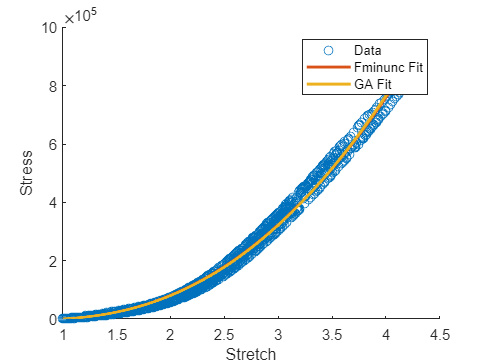



close all
hold on
scatter(stretch, stress, 'DisplayName', 'Data')
plot(stretch, func(x1, stretch), 'DisplayName', 'Fminunc Fit', 'LineWidth', 2)
plot(stretch, func(x, stretch), 'DisplayName', 'GA Fit', 'LineWidth', 2)
xlabel('Stretch')
ylabel('Stress')
legend ('show')



GArSquared = coeffDet(x, stretch)

GArSquared = 0.9893

LSQrSquared = coeffDet(x1, stretch)

LSQrSquared = 0.9893

x = 1.0e+04 *

   -2.1109    0.0002    5.7774    0.0002   -2.9387    0.0001


x1 = 1.0e+04 *

   -2.1109    0.0001    5.7774    0.0002   -2.9387    0.0001


changes =     0.0026    0.2190    0.0026    0.0362    0.0026    0.0072
